clear all;close all;clc
extCoeffFile = 'C:\Users\xiaodanwang\Documents\GitHub\BauerLab\MATLAB\parameters\prahl_extinct_coef.txt';


load('D:\Data\181031\181031-GcampM2-stim1-datahbFluo.mat'); % xform_hb, xform_fluor
% xform_hb is in mmol/liter
% xform_fluor is ratio change from baseline

% xform_hb = xform_datahb;
% xform_fluor = 0.02*(rand(128,128,301) - 0.5);

blueWavelength = 458; % nm
greenWavelength = 522;

Getting optical properties

[lambda, extCoeff]=mouseAnalysis.expSpecific.getHb(extCoeffFile);

blueLambdaInd = find(lambda == blueWavelength);
greenLambdaInd = find(lambda == greenWavelength);

hbOAbsCoeff = extCoeff([blueLambdaInd greenLambdaInd],1);
hbRAbsCoeff = extCoeff([blueLambdaInd greenLambdaInd],2);

Hb correction

fluorCorr = mouseAnalysis.physics.correctHb(xform_fluor,xform_hb,...
    hbOAbsCoeff,hbRAbsCoeff);


Plot

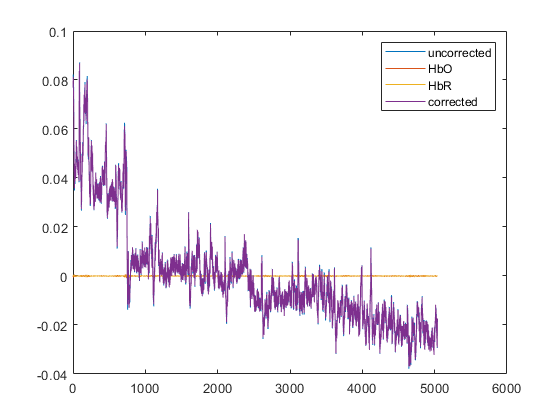

plot(squeeze(xform_fluor(60,80,1,:)))
hold on;
plot(squeeze(xform_hb(60,80,1,:)))
plot(squeeze(xform_hb(60,80,2,:)))
plot(squeeze(fluorCorr(60,80,1,:)))
legend('uncorrected','HbO','HbR','corrected')
hold off;